# ECSE 343:   Assignment 1

**Due Date: 1st February 2024    **

Name: Marc-Antoine Nadeau

Student Id.: 261114549

## Question 1: 16-bit floating point format. (5marks)

The half-precision (16-bit) floating point is one of the ways to store the numbers in computer memory. The half-precison has the following format,

- Sign Bit: 1 bit 

- Exponent: 5 bits 

- Mantissa: 10 bits  

For all questions, show your work and justify your answers. 

a) How many positive numbers can be exactly represented in this floating point format as normalized floating point values. Express you answer as a formula in terms of the number of bits in the Matissa and in the Exponent, as well as a final value. Justify your answer.

- The half-precision (16-bit) floating point can be represented as ${\left(-1\right)}^{b_{15} } 1\ldotp M\times 2^e$ where $M=b_9 \ldotp \ldotp \ldotp b_0 \;\;\&\;\;e=b_{14} \ldotp \ldotp \ldotp b_{10} -15=E-15\;\left(\textrm{except}\;\textrm{for}\;00000\;\textrm{and}\;11111\right)$

- Let |M| = Number of bits representing the Mantissa & |E| = Number of bits representing the Exponent  

- *The posssible combinations for the sign (*$\left.b_{15} \right)$*: 1 (because we are only concerned with the positive normalized floating point values)*

- *There are  *$2^{|E|} -2=30$ po*ssible value for the exponent (as we have two speciale cases) *

- *There are *$2^{|M|} =2^{10} =1024\;$equally spaced values at each value of E 

- * As such, there is *$2^{|M|} \times \left(2^{|E|} -2\right)=1024\times 30=30\;720$$\;$

b) What is the largest number that can be represented using half-precision format?

- *The largest value will be obtained when the exponent is 11110 and the Mantissa filled with 1's.  *

- *Largest_value = *${\left(-1\right)}^0 1\ldotp 111\;111\;111\;1\times 2^{11110-15} =\sum_{n=0}^{10} \frac{1}{2^n }\times 2^{15} =\frac{2047}{1024}\times 2^{15} =65\;504$

- **** Note we do not use E = 11111 because it is reserved for a special case*

c) What is the smallest normalized number that can be written in half-precision format?

- *The smallest *normalized number that can be written in half-precision format* will be obtained when the exponent is 00001 and the Mantissa filled with 0's.  *

- *Smallest Value = *${\left(-1\right)}^0 1\ldotp 000\;000\;000\;0\times 2^{00001-15} =1\times 2^{-14} =2^{-14} =0\ldotp 000\;061\;035$

- **** Note we do not use E = 00000 because it is reserved for a special case*

d) What is the smallest sub-normal (denormalized) number which can be represented in  half-precision format?

- *The smallest *smallest sub-normal (denormalized) number which can be represented in half-precision format *will be obtained when the exponent is 00000 and  all the bits of the Mantissa but the least significant be filled with 0's*

- *Smallest Value = *${\left(-1\right)}^0 0\ldotp 000\;000\;000\;1\times 2^{00000-15} =0\ldotp 000\;000\;000\;1\times 2^{-14} =2^{-10} \times 2^{-14} =2^{-24} =5\ldotp 960\;464\;\ldotp \ldotp \ldotp \times {10}^{-8} \;$

- **** Note we use E = 00000 because it is reserved for a subnormal case*

## Question 2 (5marks)

By default MATLAB uses double precision format (i.e. 64-bit floating point fomat) to store the numbers. However,  we can store a number in computer memory in different floating-point format. For example, we can store a number in half precision (16-bit) format as shown in the cell below.


x = half(0); % here we have instantiated x in the half-precion format.
whos x

  Name      Size            Bytes  Class    Attributes

  x         1x1                 2  half               




% % Any computations thus made using the variable x will be stored in half-precision format.
% NOTE: You might need to download a toolbox named Fixed Point Designer which is freely available in MATLAB.

(a) Write a MATLAB program that sums up $\frac{1}{n}$ for $n = 1, 2, . . . , 10000$ in double format (the default format in MATLAB).

upperBoundSum = 10000;
lowerBoundSum = 1;
summationResult = 0;

while lowerBoundSum<= upperBoundSum
    summationResult = summationResult + 1/lowerBoundSum;
    lowerBoundSum = lowerBoundSum+1;
end
summationResult

summationResult = 9.7876

(b) Write a MATLAB program that sums  $\frac{1}{n}$ for $n = 1, 2, . . . , 10000$ in half precsion format.

x1 = half(0); % Here I have already initialized the variable x1 in half-precision format.
upperBoundSum = 10000;
lowerBoundSum = 1;

while lowerBoundSum <= upperBoundSum
    x1 = x1 + 1/half(lowerBoundSum);
    lowerBoundSum = lowerBoundSum + 1;
end
x1

x1 = 

  half

    7.0859



(c) Write a MATLAB program that sums  sums up the same airthmatic sequence in in reverse order, i.e., for $n=10000,...,2,1$ 

x2 = half(0);  % Here I have already initialized the variable x2 in half-precision format.
upperBoundSum = 10000;
lowerBoundSum = 1;

while upperBoundSum >= lowerBoundSum
    x2 = x2 + 1/half(upperBoundSum);
    upperBoundSum = upperBoundSum - 1;
end
x2

x2 = 

  half

    9.7969



Compare the results obtatined in parts (b) and (c) with the results obtained in part (a) and explain your observations.

- *The results obtained in (a) is *$\sim 9\ldotp 7876$, in (b) $\sim 7\ldotp 0859$ and in (c) $\sim 9\ldotp 7969\ldotp$ Among the values previously listed, we expected the value of (a) to be closest to the real partial sum. This is because we use double precision in (a) as opposed to half-precision in (b) and (c). In other words, a lot more values get approximated (round-off error) when using half-precision, these small errors with propagate through the sum and accentuate the errors. 

- The value of (b) is far from both (a) and (c), this is a combination of both half-precision as discuss above and forward order summation. The error is much greater in (b) because than in (c) because we are summing starting at the largest value which creates a lost of precison for the smaller values. On the contrary, with the reverse sum in (c), we are starting at the smallest values which reduces the errors.

## Question 3 (5marks)

In this question you are tasked with computing the sum of the elements in a vector. 

a) Run the following code cell to compute the sum of the elements in a vector. Explain the discrepancy between the results obtained with MATLAB's in built function and the analytical solution. 

N = 30000000;
rng(200);                     % select random seed for reproducible resutls
XL = normrnd(1,0.1,N,1);      % Generate normal random numbers
X  = single(XL);              % Convert to single precision float

D_sum = sum(XL);              % We use the double precision sum as the "exact" ground truth.

tic
S1 = sum(X);                  % use in built MATLAB function to compute the sum
toc

Elapsed time is 0.002314 seconds.


Error1 = abs(D_sum-S1)/D_sum  % compare the results

Error1 = single
8.1439e-08

- According to the code, we are instantiating a vector of double precision values and then we are converting each elements to single precision values. When we convert it we are losing precison as we must accomodate the smaller memory size of single precision.

- As a result, the error accumulates when computing the sum of all elements as we are adding each element in the vector which have been truncated. Therefore, we are losing accuracy as opposed to the built-in function, and this is worsen when we are summing large quantity of numbers as is the case here.

b) Write a function S = naiveSum(X) that incrementally computes the sum of the values $x_1$, $x_2$, ..., $x_n$ incrementally:


$$S_1 = x_1 $$



$$S_2 = S_1 + x_2$$



$$\vdots$$



$$S_n = S_{n-1} + x_n$$


This can be implmented using a for-loop in matlab.

Test your function using the following code:

N = 30000000;
rng(200);                 % select random seed for reproducible resutls
XL = normrnd(1,0.1,N,1);  % Generate normal random numbers
X  = single(XL);           % Convert to single precision float


D_sum = sum(XL);  % We use the double precision sum as the "exact" ground truth.

tic
S2 = naiveSum(X); % use your function to compute the sum
toc

Elapsed time is 0.035617 seconds.



Error2 = abs(D_sum-S2)/D_sum  % compare the results

Error2 = single
3.0919e-05

c) Write a function S =  *rSum(X) *that uses recursion to compute the sum of the elements provided in the vector X.  This approach is summarized as follows.


$$S(X) = 
     \begin{cases}
       0 &\quad  \text{if   } n=0 \\
       x_1 &\quad \text{if   } n=1  \\
     S(X(1:n/2))+S(X(n/2 +1 : n) &\quad\text{if   } n>1 \\ 
     \end{cases}$$


Note that $n$ is the number of elements in X. Also be careful to address the case where $\frac{n}{2}$ is not an integer. Use the following code to test your function.

N = 30000000;
rng(200);                 % select random seed for reproducible resutls
XL = normrnd(1,0.1,N,1);  % Generate normal random numbers
X  = single(XL);          % Convert to single precision float

D_sum = sum(XL);  % We use the double precision sum as the "exact" ground truth.

tic
S3 = rSum(X); % use your function to compute the sum
toc

Elapsed time is 6.195318 seconds.



Error3 = abs(D_sum-S3)/D_sum  % compare the results

Error3 = single
5.1897e-08

d) The recursive function calls add a significant amount of cpu cost in the algorithm in part c. Propose, implement, and test a compromise algorithm using both the naive and recursive approach that has both good accuracy and good cpu cost. Compare your algorithm to the MATLAB function sum. Explain your design decision for the proposed algorithm. Test your algorithm in the following code cell:

N = 30000000;
rng(200);                 % select random seed for reproducible resutls
XL = normrnd(1,0.1,N,1);  % Generate normal random numbers
X  = single(XL);          % Convert to single precision float

D_sum = sum(XL);  % We use the double precision sum as the "exact" ground truth.

tic
S4 = improvedSum(X); % use your function to compute the sum
toc 

Elapsed time is 0.104947 seconds.


Error4 = abs(D_sum-S4)/D_sum  % compare the results)

Error4 = single
1.4771e-08

- *The proposed algorithm makes use of iterative and recursive summing technique. We first hardcode a constant (which can be modified), a higher constant will ****tend**** to make the algorithm quicker but less precise, whereas a small constant will ****tend**** to make it quicker but less precises. *

- If the length exceeds the threshold, it recursively divides the vector into two halves. When the size of the vector is smaller than THRESHOLD, the algorithm calls the `naiveSum` function to calculate the sum of the elements in the vector.

e) Explain the difference in accuracy and cpu cost for the above methods for computing the sum. 

- ***Naive (Iterative Sum) :***

- *Accuracy: This summing technique should be relatively precise for smaller arrays, but *accumulation of rounding errors may lead to loss of precision, especially for large arrays or arrays with a wide range of values as is our case here.

- *CPU Cost: This summing technique yields results the quickest as MATLAB iterates quickly over arrays.*

- ***Recursive Sum: ***

- *Accuracy: The accuracy of this technique should be higher than the naive. By iteratively breaking down the array into smaller segments, summing their contents, and then aggregating these subarryas. Hence, this version of the algorithm adds values that are likely of similar magnitude reducing round off errors. *

- CPU Cost: This summing technique is very expansive for the CPU has it involves lots functions called which are expensive in nature

- **Improved Sum **(assuming THRESHOLD = 10 000) **: **

- Accuracy: As in the recursive sum, the accuracy of this should be high as it breaks the array into a smaller ones which then calls the naive sum which, as mentionned above, quite precise for relatively small arrays

- CPU Cost: This summing technique is not to expansive as we are avoiding most of the funcitons calls in recurisve sum and replacing them by the much quicker naive approach.

## Question 4: (5marks)

The derivative of a function, f(x), can be computed using the finite difference method, which can be derived using the first-order terms of the Taylor series expansion of the function, about : 

$f{\left(x_0 +h\right)}=f{\left(x_0 \right)}+hf^{\prime } {\left(x_0 \right)}+\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h^2 +\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^3 +\ldots$               (4.1)

Rearranging terms to solve for $f^{\prime } {\left(x_0 \right)}$  and ignoring (truncating) the higher-order terms, we obtain the first order approximation of derivative

$f^{\prime } {\left(x_0 \right)}\;\approx \frac{f{\left(x_0 +h\right)}-f{\left(x_0 \right)}}{h}$                 (4.2)

(a) What is the truncation error for the above approximation? How does the trunction error behave with decrease in the value of $h$ ?

*Starting from the equation 4.1, we make the following modificaitons*


$$f{\left(x_0 +h\right)}=f{\left(x_0 \right)}+hf^{\prime } {\left(x_0 \right)}+\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h^2 +\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^3 +\ldots$$



$$f{\left(x_0 +h\right)}\;-f{\left(x_0 \right)}\;=hf^{\prime } {\left(x_0 \right)}+\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h^2 +\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^3 +\ldots\;$$



$$\frac{f{\left(x_0 +h\right)}\;-f{\left(x_0 \right)}}{h}\;=\frac{hf^{\prime } {\left(x_0 \right)}+\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h^2 +\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^3 +\ldots\;}{h}$$



$$\frac{f{\left(x_0 +h\right)}\;-f{\left(x_0 \right)}}{h}=f^{\prime } {\left(x_0 \right)}+\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h+\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^2 +\ldots\;$$



$$\frac{f{\left(x_0 +h\right)}\;-f{\left(x_0 \right)}}{h}=f^{\prime } {\left(x_0 \right)}\;+\phi \;\;$$


Where $\phi$ is the truncation error $\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h+\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^2 +\ldots\;$. Hence, we obtain the approximation:


$$f^{\prime } {\left(x_0 \right)}\;\approx \frac{f{\left(x_0 +h\right)}-f{\left(x_0 \right)}}{h}$$


As the value of h decreases, the higher-order terms become more and more negligable. Namely, 


$$\lim_{h\to 0} \phi =\;\lim_{h\to 0} \;\left(\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h+\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^2 +\ldots\right)=0$$


As such, in a pure mathematical approach (ignoring all the numerical errors), the smaller the h, the more precise the derivative becomes.

(b) To compute the derivative of $f (x) = sin(x)$, we can use the equation (4.2) as,

                        $\frac{d sin(x)} {dx}  \approx$ $\frac{\sin {\left(x+h\right)}-\sin {\left(x\right)}}{h}$                             (4.3)

 In the cell below, write a MATLAB program that can compute the derivative of the $sin(x)$ at $x=45$ for different values of $h$. Use $h=10^{-19},10^{-18}, 10^{-17} ,..., 10^{-2}, 10^{-1}, 1$.

We know the true value of derivative of $sin(x)$ at $x=45$ is $cos(45)$. Plot the absolute error vs $h$.  Make sure the axis are labeled and the plot has an appropriate title.

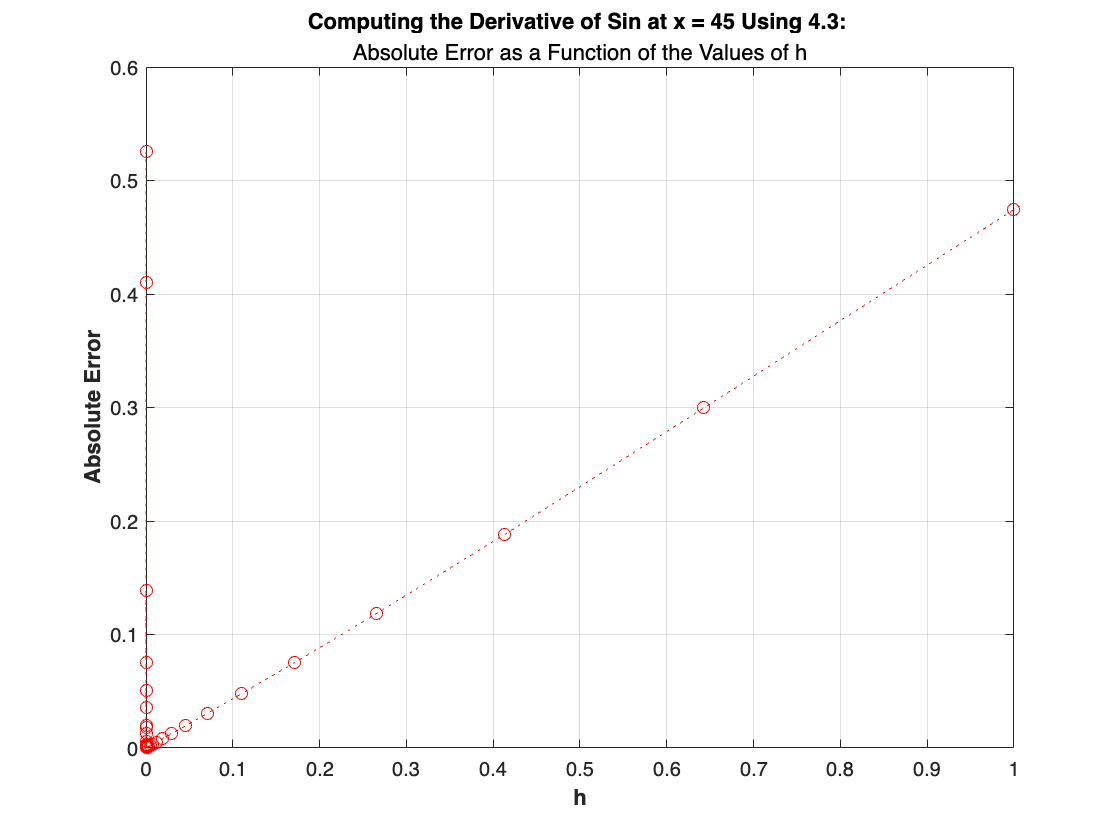

true_derivative = cos(45);
h = logspace(-19,0,100);  % h is a vector here that contains 100 values between 10^(-19) to 1
errors = zeros(length(h),1);

for i = 1:length(h)
    derivative = ( sin(45+h(i)) - sin(45) ) / h(i);
    errors(i) = abs(true_derivative - derivative);
end
plot(h, errors, ':or');
xlabel('h', 'FontWeight','bold');
ylabel('Absolute Error', 'FontWeight','bold');
title('Computing the Derivative of Sin at x = 45 Using 4.3: ', 'FontWeight','bold');
subtitle('Absolute Error as a Function of the Values of h', 'FontWeight','normal');
grid on;

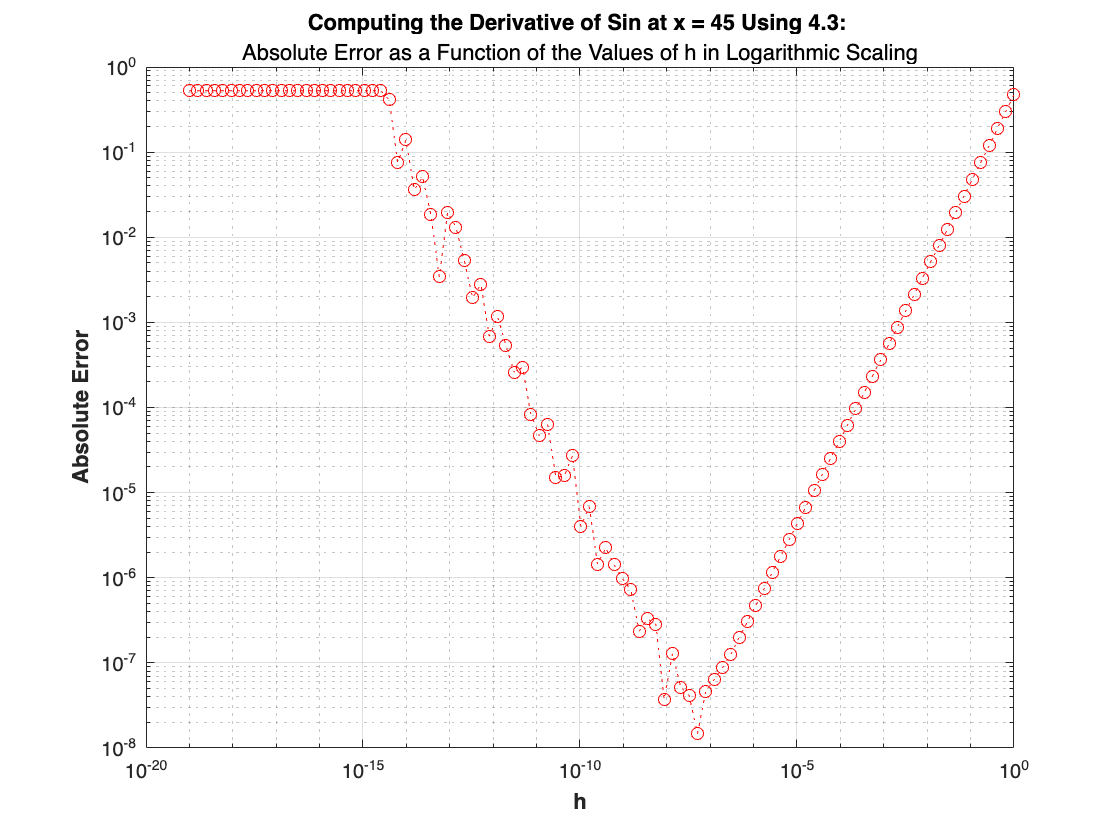

loglog(h, errors, ':or');
xlabel('h', 'FontWeight','bold');
ylabel('Absolute Error', 'FontWeight','bold');
title('Computing the Derivative of Sin at x = 45 Using 4.3: ', 'FontWeight','bold');
subtitle('Absolute Error as a Function of the Values of h in Logarithmic Scaling', 'FontWeight','normal');
grid on;

(c) The function $sin(x+h)-sin(x)$ can be transformed into another form  using the trigonometric formula

$sin(\phi) - sin(\psi) = 2 cos(\frac{\phi+\psi}{2}) sin((\frac{\phi-\psi}{2})$                                          (4.4)

Using the above formula, transform the equation (4.3) to compute the derivative of $sin(x)$ and write a MATLAB program that computes the derivative of the $sin(x)$ at $x=45$ for $h=10^{-19},10^{-18}, 10^{-17} ,..., 10^{-2}, 10^{-1}, 1$.

Compare the derivative obtained with the true value and plot the absolute error vs $h$.  Make sure the axes are labeled and the plot has an appropriate title.

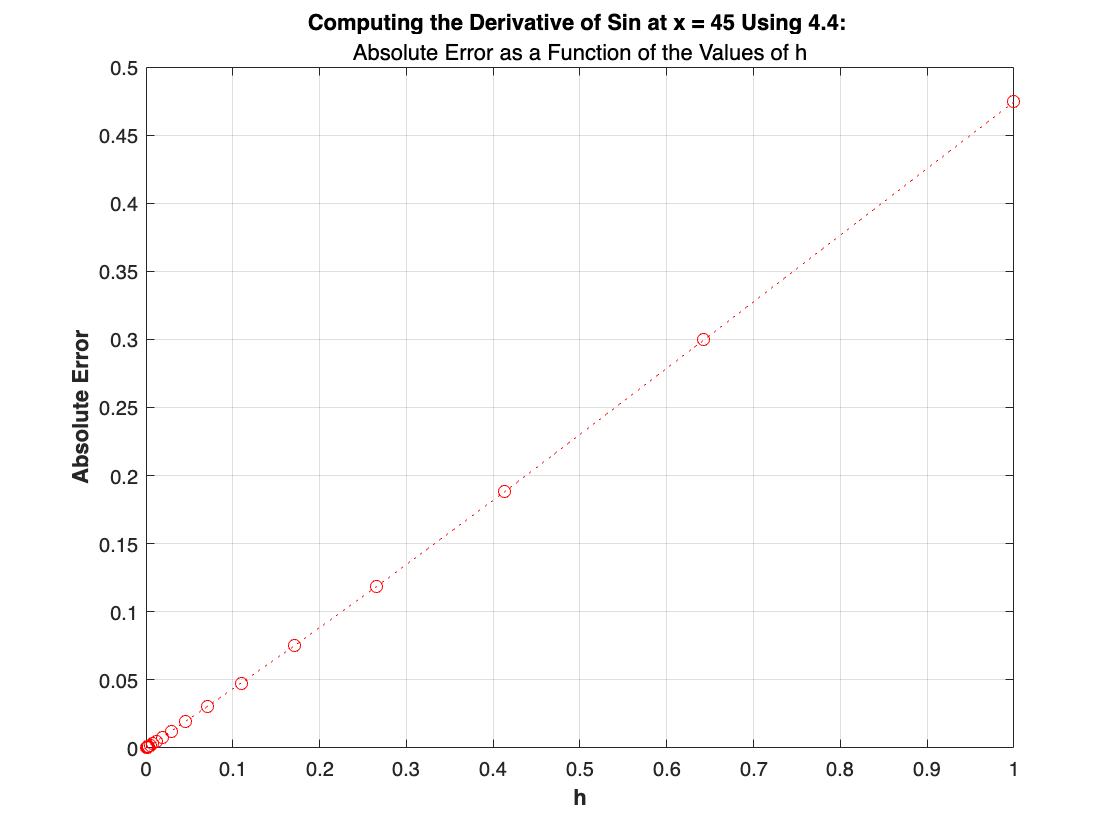

true_derivative = cos(45);
h = logspace(-19, 0, 100);
errors = zeros(length(h), 1);

for i = 1:length(h)
    derivative = (2 * cos( ( 2 * 45 + h(i) ) / 2 ) * sin( h(i) / 2 )) / h(i);
    errors(i) = abs(true_derivative - derivative);
end
plot(h, errors, ':or');
xlabel('h', 'FontWeight','bold');
ylabel('Absolute Error', 'FontWeight','bold');
title('Computing the Derivative of Sin at x = 45 Using 4.4: ', 'FontWeight','bold');
subtitle('Absolute Error as a Function of the Values of h', 'FontWeight','normal');
grid on;

(d) Explain the difference in accuracy between the results obtained in part (b) and (c). 

- *In part b when h is too small, we are likely to get a chatastropic cancellation as *$\lim_{h\to 0} \;\sin \left(x+h\right)=\;\sin \left(x\right)$. This explains why the value of the error is minimized at a relatively large value of h. 

- To avoid such catastrophic cancellation and provide numerical stability to the algorithm, we use trig identity in 4.4 and avoid substractions. As such, we obtain a trend where the smaller the h, the smaller the error which increase precision.

## Question 5: Solving linear systems of equations. (10 marks)

    a) Write the  functions named *forward_sub *to perform the forward substitution on a lower triangular matrix. Add your function in the appendix of this file.

You can check your function by comparing the obtained results with the MATLAB's built in backslash operator. 

 Use the cell below to test the correctness of your function on the provided lower triangular matrix.  

 A = tril(magic(4)) % A is a 4x4 lower triangular matrix   

A =     16     0     0     0
     5    11     0     0
     9     7     6     0
     4    14    15     1


 b = [1; 2; 3; 4];     % right hand side vector of size 4x1

%---------------------------------------------------------------------------------------------------------
 % call your forward_sub function and solve  Ax = b    % (where A is a
 % lower triangular square matrix)

 disp('Solution using A \ b')

Solution using A \ b


 x_backslash = A \ b

x_backslash =     0.0625
    0.1534
    0.2273
   -1.8068


disp('Solution using forward_sub');

Solution using forward_sub


 x_forward_sub = forward_sub(A, b)

x_forward_sub =     0.0625
    0.1534
    0.2273
   -1.8068


 b) Write the *backward_sub *function to perform the backward substitution on a lower triangular matrix. Add your function in the appendix of this file.

 Use the cell below to test the correctness of your function by comparing your solution with the MATLAB's built in backslash operator.

  A = triu(magic(4)) % A is a 4x4 upper triangular matrix   

A =     16     2     3    13
     0    11    10     8
     0     0     6    12
     0     0     0     1


 b = [1; 2; 3; 4];     % right hand side vector of size 4x1

%---------------------------------------------------------------------------------------------------------
 % call your backward_sub function and solve  Ax = b    % (where A is a
 % upper triangular square matrix)

 disp('Solution using A \ b');

Solution using A \ b


 x_backslash = A \ b;
 disp('Solution using backward_sub');

Solution using backward_sub


x_backward_sub = backward_sub(A, b)

x_backward_sub =    -2.2926
    4.0909
   -7.5000
    4.0000


    c) Write a function named *LU_decomposition.m * in the Appendix of this file to compute the LU factorization using Gaussian Elimination. 

    d)  In the cell below use the LU decomposition implemented in part (c) along with forward and backward substitution functions written in part (a)  and (b), respectively, to solve the following system of equations. List the values of vector X obtained.  


$$\underset{A}{\underbrace{{\left[\begin{array}{cccc}
1e-16 & 50 & 5 & 9\\
0.2 & 5 & 7.4 & 5\\
0.5 & 4 & 8.5 & 32\\
0.89 & 8 & 11 & 92
\end{array}\right]}} } \underset{X}{\underbrace{{\left[\begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right]}} } =\ \underset{b}{\underbrace{{\left[\begin{array}{c}
40\\
52\\
18\\
95
\end{array}\right]}} }$$


A = [ 1e-16 50 5 9;
      0.2 5 7.4 5;
      0.5 4 8.5 32;
      0.89 8 11 92;];

b = [ 40 ; 52 ; 18; 95; ];

[L, U] = LU_decompositon(A);


y = forward_sub(L,b);



withoutPivotingX = backward_sub(U,y);

withoutPivotingResidual = b - A * withoutPivotingX

withoutPivotingResidual =          0
   30.5308
   28.7878
   65.3048


matlabX = A\b;

matlabResidual = b - A * matlabX

matlabResidual = 1.0e-13 *

   -0.0711
    0.5684
    0.2842
    0.5684


   *LU_rowpivot.m *to compute the Gaussian Elimination based LU factorization **using the partial pivoting** (row pivoting). Choose the elements with maximum magnitude as pivots. The function should take matrix  as the input and should output L, U and P matrices. Write your function in the Appendix of this file.

 f) In the cell below use the LU decomposition with partial pivoting implemented in part (b) along with forward and backward substitution functions written in part (c) to solve the above system of equations. List the values of vector X obtained.  of vector X obtained.  

A = [ 1e-16 50 5 9;
      0.2 5 7.4 5;
      0.5 4 8.5 32;
      0.89 8 11 92;];

b = [ 40 ; 52 ; 18; 95; ];

[L, U, P] = LU_rowpivot(A);

y = forward_sub(L,P * b);


pivotingX = backward_sub(U,y);
pivotingResidual = b - A * pivotingX

pivotingResidual = 1.0e-13 *

   -0.0711
    0.5684
    0.2842
    0.5684



matlabX= A\b;
matlabResidual = b - A * matlabX

matlabResidual = 1.0e-13 *

   -0.0711
    0.5684
    0.2842
    0.5684


   g) Comment on solutions obtained in part (d) and (f). Use the residual to determine which solution is more accurarte.

-     The value of the first pivot A (i.e. $A_{11} =1e-16$) in LU decomposition without partial pivoting makes the LU decomposition numercial unstable because of the limited storing capactity (precison).  As a result we      obtain large residual values signifying a substantial deviation between the calculated and actual solutions. 

-     On the contrary, when we introduce partial pivoting we mitigate the errors as we are chosing the best pivoting in each columns, this ensures numerical stability and smaller residuals. In fact, these residuals values are similar to the in-built (i.e. $\left.A\;\backslash \;b\right)$ matlab function.

## Appendix

###  Write functions for Question 3 are here.

function S = naiveSum(X)
% returns the sum of all elements in vector X
   S = 0;
   for i = 1:length(X)
       S = S + X(i);
   end
end

%--------------------------------------------------------------------------

function S = rSum(X)
% Returns the sum of all elements in vector X using the recurssion
    N = length(X);
    if N == 0
        S = 0;
    elseif N == 1
        S = X(1);
    else 
        S = rSum(X(1:floor(N/2))) + rSum(X(floor(N/2) + 1:end));
    end
end

%--------------------------------------------------------------------------
function S = improvedSum(X)
% Returns the sum of all elements in vector 
    THRESHOLD = 10000;
    N = length(X);
    if N <= THRESHOLD
        S = naiveSum(X);
    else
        S = improvedSum(X(1:floor(N/2))) + improvedSum(X(floor(N/2) + 1:end));
    end
end


### Write code for Question 5 here

function [L, U] = LU_decompositon(A)
% L  is lower triagular matrix
% U is upper triangular matrix 

   [~,n] = size(A);

   % Identity matrix of size A - Starting Point of L 
   L = eye(n);
  

   % Initiliaze U to A - Starting Point of U 
   U = A;

   for k = 1:n-1 % Since we have a square matrix, no need to reach last row of U
       
       for i = k + 1:n % Start at the value under the pivot and till we reach the end
         
           % Pivot chosen in diagonal which is why we use columns x columns
           L(i, k) = U(i, k) / U(k, k);

           U(i, k:n) = U(i, k:n) - L(i, k) * U(k, k:n);
       end
       
   end
   
end


function [L, U, P] = LU_rowpivot(A)
% L  is lower triagular matrix
% U is upper triangular matrix 
% P is the permutation matrix
% P*A = L*U

    [numRows , numCols] = size(A);
    
    U = A;
    L = eye(numCols);
    P = eye(numCols);

    for k = 1:numCols - 1

        %Finding the maximum in the column k start where row = k
        % U -> start: row == column: end at last
        [~, rowIndex] = max( abs( U( k: end, k )));
        
        
        % Index Offset
        rowIndex = rowIndex + k - 1; 
        
        % Switch rows in U   
        tmpU = U(k,:);
        U(k,:) = U(rowIndex, :);
        U(rowIndex, : ) = tmpU;

        % Switch row in P
        tmpP = P(k,:);
        P(k,:) = P(rowIndex, :);
        P(rowIndex, :) = tmpP; 

        % Switch rows in L
        tmpL = L(k, 1: k - 1);
        L(k, 1: k - 1) = L(rowIndex, 1:k-1);
        L(rowIndex, 1:k-1) = tmpL;
   
        for rows = k + 1:numRows % Start at the value under the pivot and till we reach the end
           
           % Pivot chosen in diagonal which is why we use columns x columns
           L(rows, k) = U(rows, k) / U(k, k); 

           U(rows, k: end) = U(rows, k: end) - L(rows, k) *  U(k, k: end);
        end
    end 
end

function y = forward_sub(L,b)
% y is the vector - Here we let Ux = y to solve for LUx = b  
% L is the lower triangular matrix
% Ly = b --> solve with forward sub

    n = length(b); % Should get us the height of the vector 
    y = zeros(n, 1); % Initialized an n rows by 1 column matrix with all elements set to 0
    for i = 1:n 
         
        y(i) = ( b(i) - L(i, 1:i-1) * y(1:i-1,1) ) / L(i,i) ;
    end
end 

function X = backward_sub(U,y)
% X is the vector 
% U is the upper triangular matrix
% Ux = y --> solve with backward sub

    n = length(y); % Should get us the height of the vector
    X = zeros(n, 1); % Initialized n rows by 1 column matrix with all elements set to 0
    for i = n:-1:1 
        
        X(i) = ( y(i) - U(i, i+1: n) * X(i+1:n, 1) ) / U(i,i);
    end
end 